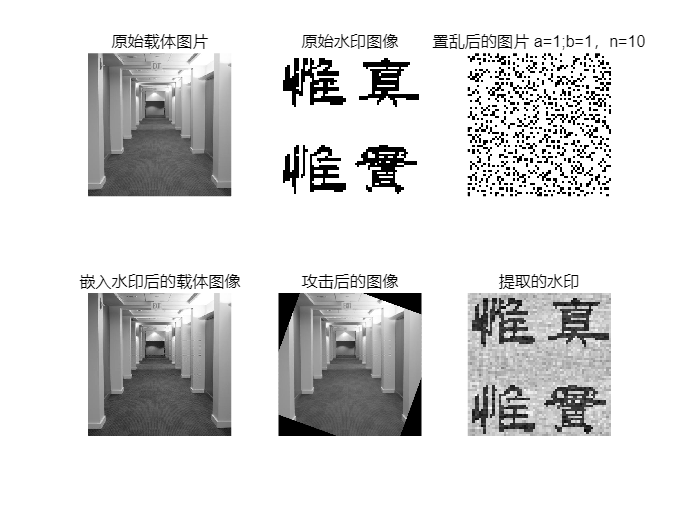

close all
clc
clear 

M = 512; % 原图像长度
N = 64; % 水印图像长度

alpha=0.05;% 嵌入强度系数

% 打开原图、水印图
I = imread('hallway.jpg');
IG = imread('水印(二值).bmp');
G = IG;
subplot(2,3,1);
imshow(I);
title('原始载体图片');
subplot(2,3,2);
imshow(G,[]);
title('原始水印图像');

img=G;%读取图片，根据Arnold变换的条件，图像必须是正方形
mysize=size(img);%当只有一个输出参数时，返回一个行向量，该行向量的第一个元素时矩阵的行数，第二个元素是矩阵的列数。

%置乱与逆置乱必须采用共同参数的时候,就相当于密码，才能解密，让图像复原
n=10;%迭代次数
a=1;b=1;

%置乱操作
h = N;
w = N;
imgnnn=zeros(h,w);
for i=1:n
    for y=1:h
        for x=1:w           
            xx=mod((x-1)+b*(y-1),N)+1;   %mod取余操作，(a,b)就是a除以b的余数
            yy=mod(a*(x-1)+(a*b+1)*(y-1),N)+1;        
            imgnnn(yy,xx)=img(y,x);                
        end
    end
    img=imgnnn;
end
imgnnn = uint8(imgnnn);
 
subplot(2,3,3);
imshow(imgnnn,[])%置乱后的图片
title('置乱后的图片 a=1;b=1，n=10');
% imwrite (imgnnn,'置乱后的图片.bmp');  %生成图像保存功能

G=imgnnn;
G = double(G) * 255; % 将逻辑值 1 转换为 255

%Step 1
%对G进行SVD分解
[U,S,V] = svd(G);% 对G进行SVD分解，得到U、S、V矩阵

%Step 2
%进行2级离散小波变换
[LL1, LH1, HL1, HH1] = dwt2(I, 'haar');
[LL2, LH2, HL2, HH2] = dwt2(LL1, 'haar');%128*128

%Step 3
%选出最优嵌入块 
img=HH2;
% 初始化变量
img_size = [128 128];
sub_size = 64;
max_entropy = -Inf;
max_entropy_pos = [0, 0];
max_entropy_sub = [];

% 遍历图像中的所有64×64子片段
for i = 1:img_size(1) - sub_size + 1
    for j = 1:img_size(2) - sub_size + 1
        % 提取子片段
        sub_img = img(i:i+sub_size-1, j:j+sub_size-1);
   
        % 计算子片段的信息熵
        current_entropy = entropy(sub_img);
        
        % 更新最大信息熵及其位置
        if current_entropy > max_entropy
            max_entropy = current_entropy;
            max_entropy_pos = [i, j];
            max_entropy_sub = sub_img;
        end
    end
end

i = max_entropy_pos(1);
j = max_entropy_pos(2);

H_I = HH2(i:i+sub_size-1, j:j+sub_size-1);
B = dct2(H_I);

%Step 5
%对B进行奇异值分解,嵌入水印
[U1,S1,V1] = svd(B);
S2 = S1 + alpha * S;
B1 = U1 * S2 * V1;
H_I = idct2(B1);
HH2(i:i+sub_size-1, j:j+sub_size-1) = H_I;
LL1 = idwt2(LL2,LH2,HL2,HH2,'haar');
W = idwt2(LL1,LH1,HL1,HH1,'haar');
W = uint8(W);
aW = W;

%% 攻击
% aW = imread('hallway.jpg');

% %高斯滤波攻击
% H = fspecial('gaussian',3,0.4);
% aW = imfilter(aW,H);


% 中值滤波
% % I_gray = im2double(imread('input.jpg')); 
% aW=im2double(aW);
% % 3×3中值滤波（自动处理边界）
% aW = medfilt2(aW, [3 3]); 
% % 灰度图像处理
% aW = medfilt2(aW, [3 3]); % 3x3邻域


%均值滤波
% % 创建3×3均值滤波器核
% meanKernel = fspecial('average', [3 3]); 
% aW=im2double(aW);
% % 应用滤波（自动处理灰度/彩色）
% aW = imfilter(aW, meanKernel, 'replicate');
% 方法1：使用预定义滤波器
% H = fspecial('average', 3); % 3x3均值滤波器
% aW = imfilter(aW, H);
% 方法2：直接指定滤波类型
% aW = imfilter(aW, ones(3)/9); % 3x3均值滤波



%高斯噪声
% mean = 0; % 均值为0
% variance = 0.001; % 方差为0.01
% 
% aW = imnoise(aW, 'gaussian', mean, variance);



% JPEG压缩攻击
% quality = 50;
% imwrite(aW, 'temp.jpg', 'Quality', quality); % 保存为JPEG格式
% aW = imread('temp.jpg'); % 重新读取JPEG图像

% 
% 剪切攻击
% 

% r = 0.25; % 剪切比例为30%
% sz = size(W);
% h1 = round(sz(1)*r); % 剪切高度
% w1 = round(sz(2)*r); % 剪切宽度
% x1 = round(rand(sz(1)-h1)); % 随机选择一行
% y1 = round(rand(sz(2)-w1)); % 随机选择一列
% % x1=300;
% % y1=300;
% aW(x1+1:x1+h1, y1+1:y1+w1) = 0; % 将指定区域置为0
% % % % 

% 旋转攻击
% 
angle =20; % 旋转角度为20度
aW = imrotate(aW, angle, 'bilinear', 'crop');

% aW = imrotate(aW, -angle, 'bilinear', 'crop');
% 

%斑点噪声
% 使用imnoise函数直接添加
% aW = imnoise(aW, 'speckle', 0.01); % 参数为方差（建议0.01~0.1）


% 椒盐噪声
% 添加椒盐噪声（密度5%）
% aW = add_salt_pepper(aW, 0.01);

%斑点噪声

% aW = imnoise(aW, 'speckle', 0.05);  % 方差建议范围0.01-0.1


% 
% tif=imread("cameraman.tif");
% aW = padarray(tif, [256, 256], 'post');  % 在图像右侧和下方填充128像

%
% % aW = rand(512, 512);



%实际
% %步骤1: 原始图像
% img = im2double(aW);
% 
% %步骤2: JPEG压缩（模拟带宽限制）
% imwrite(img, 'temp.jpg', 'Quality', 70);
% compressed_img = imread('temp.jpg');
% 
% % 步骤3: 转换为信号并添加噪声
% signal = compressed_img(:); % 图像转为信号
% signal = double(signal);
% snr = 15; % 信噪比15dB
% noisy_signal = awgn(signal, snr, 'measured');
% 
% % 步骤4: 数据包丢失（模拟网络拥塞）
% packet_size = 64; % 64字节/包
% num_packets = floor(length(noisy_signal)/packet_size);
% lost_packets = randperm(num_packets, floor(num_packets*0.05)); % 丢包率20%
% noisy_signal(lost_packets*packet_size : (lost_packets+1)*packet_size) = 0;
% 
% % 步骤5: 恢复图像
% rx_img = reshape(noisy_signal, size(compressed_img));
% rx_img = im2double(rx_img);
% 
% % 步骤6: 解码后处理（去噪）
% 
% denoised_img = medfilt2(rx_img, [3 3]);
% 
% aW=uint8(denoised_img);



%% SURF特征匹配法
% 读取图像
refImg = I;
rotatedImg =aW;

% 检测SURF特征点
refPoints = detectSURFFeatures(refImg);
rotatedPoints = detectSURFFeatures(rotatedImg);

% 提取特征描述子
[refFeatures, refValidPoints] = extractFeatures(refImg, refPoints);
[rotFeatures, rotValidPoints] = extractFeatures(rotatedImg, rotatedPoints);

% 特征匹配
indexPairs = matchFeatures(refFeatures, rotFeatures, 'Unique', true);

% 获取匹配点坐标
matchedRef = refValidPoints(indexPairs(:,1));
matchedRot = rotValidPoints(indexPairs(:,2));

% 计算旋转角度（RANSAC剔除异常值）
[tform, inlierIdx] = estimateGeometricTransform2D(...
    matchedRot.Location, matchedRef.Location, 'similarity');

% 提取旋转角度
rotationMatrix = tform.T(1:2,1:2);
estimatedAngle = atan2d(rotationMatrix(2,1), rotationMatrix(1,1));

% % 校正图像
% outputView = imref2d(size(refImg));
% correctedImg = imwarp(rotatedImg, tform, 'OutputView', outputView);
aW = imrotate(aW, estimatedAngle, 'bilinear', 'crop');


%提取水印
%aW=double(aW);
[LL3, LH3, HL3, HH3] = dwt2(aW, 'haar');
[LL4, LH4, HL4, HH4] = dwt2(LL3, 'haar');%128*128
H_I2 = HH4(i:i+sub_size-1, j:j+sub_size-1);
B2 = dct2(H_I2);
[Uw,Sw,Vw] = svd(B2);
Sx = (Sw - S1)/alpha;
B2 = U * Sx * V.';
A = B2;

%逆置乱复原
img2=A;%读取置乱图片
for i=1:n
    for y=1:h
        for x=1:w            
            xx=mod((a*b+1)*(x-1)-b*(y-1),N)+1;%matlab索引中不能是0，要从1开始
            yy=mod(-a*(x-1)+(y-1),N)+1  ;        
            imgnnn(yy,xx)=img2(y,x);                   
        end
    end
    img2=imgnnn;
end
imgnnn = uint8(imgnnn);

% imgnnn = imbinarize(imgnnn);  % 自动选择阈值;

subplot(2,3,4);
imshow(W,[]);
title('嵌入水印后的载体图像');
subplot(2,3,5);
imshow(aW,[]);
title('攻击后的图像');
subplot(2,3,6);
imshow(imgnnn,[]);
title('提取的水印');


% 计算PSNR值
W = uint8(W);
psnr_val = psnr(I, W);
fprintf('原图与嵌入水印后的图PSNR为： %f.\n', psnr_val);

原图与嵌入水印后的图PSNR为： 42.434325.



aW = uint8(aW);
psnr_val2 = psnr(I, aW);
fprintf('原图与嵌入水印后被攻击的图PSNR为： %f.\n', psnr_val2);

原图与嵌入水印后被攻击的图PSNR为： 13.333096.



% 计算NC值
% C = normxcorr2(IG*256, imgnnn);
% % 提取最大相关系数值
% nc_value = max(C(:));
% % 输出结果
% fprintf('归一化相关性（NC）值为：%.5f\n', nc_value);

% % 计算NC值
NC = corr2(IG*256, imgnnn);
disp(['归一化相关系数 NC = ', num2str(NC)]);

归一化相关系数 NC = 0.96611



% 计算SSIM值
[ssimval, ~] = ssim(I, W);
fprintf('SSIM值为: %.4f\n', ssimval);

SSIM值为: 0.9781




imwrite(aW, 'h6.jpg'); % 保存为JPEG格式

close all
h1 = imread('hallway.jpg');
h2 = imread('fabric.jpg');
h3 = imread('Peppers.jpg');
h4 = imread('liftingbody.png');

subplot(2,2,1);
imshow(h1,[]);
title('Hallway');
subplot(2,2,2);
imshow(h2,[]);
title('Dog');
subplot(2,2,3);
imshow(h3,[]);
title('Peppers');
subplot(2,2,4);
imshow(h4,[]);
title('Liftingbody');


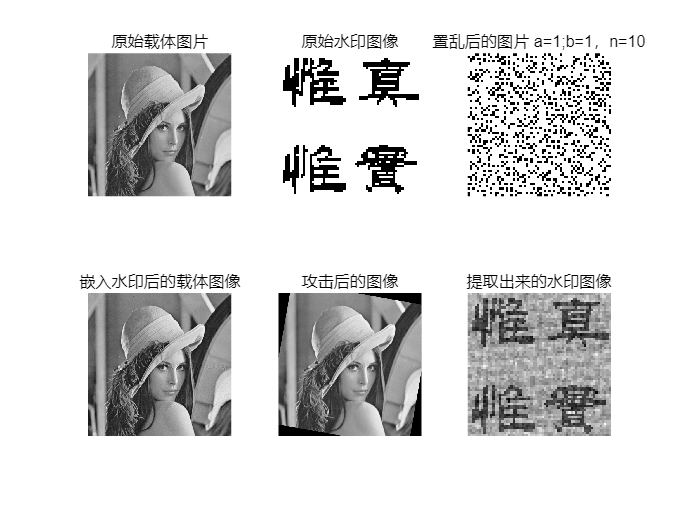

close all
clc
clear 

M = 512; % 原图像长度
N = 64; % 水印图像长度

alpha=0.05;% 嵌入强度系数

% 打开原图、水印图
I = imread('lena.jpg');
IG = imread('水印(二值).bmp');
G = IG;
subplot(2,3,1);
imshow(I);
title('原始载体图片');
subplot(2,3,2);
imshow(G,[]);
title('原始水印图像');

img=G;%读取图片，根据Arnold变换的条件，图像必须是正方形
mysize=size(img);%当只有一个输出参数时，返回一个行向量，该行向量的第一个元素时矩阵的行数，第二个元素是矩阵的列数。

%置乱与逆置乱必须采用共同参数的时候,就相当于密码，才能解密，让图像复原
n=10;%迭代次数
a=1;b=1;

%置乱操作
h = N;
w = N;
imgnnn=zeros(h,w);
for i=1:n
    for y=1:h
        for x=1:w           
            xx=mod((x-1)+b*(y-1),N)+1;   %mod取余操作，(a,b)就是a除以b的余数
            yy=mod(a*(x-1)+(a*b+1)*(y-1),N)+1;        
            imgnnn(yy,xx)=img(y,x);                
        end
    end
    img=imgnnn;
end
imgnnn = uint8(imgnnn);
 
subplot(2,3,3);
imshow(imgnnn,[])%置乱后的图片
title('置乱后的图片 a=1;b=1，n=10');
% imwrite (imgnnn,'置乱后的图片.bmp');  %生成图像保存功能

G=imgnnn;
G = double(G) * 255; % 将逻辑值 1 转换为 255

%Step 1
%对G进行SVD分解
[U,S,V] = svd(G);% 对G进行SVD分解，得到U、S、V矩阵

%Step 2
%进行2级离散小波变换
[LL1, LH1, HL1, HH1] = dwt2(I, 'haar');
[LL2, LH2, HL2, HH2] = dwt2(LL1, 'haar');%128*128

%Step 3
%选出最优嵌入块 
img=HH2;
% 初始化变量
img_size = [128 128];
sub_size = 64;
max_entropy = -Inf;
max_entropy_pos = [0, 0];
max_entropy_sub = [];

% 遍历图像中的所有64×64子片段
for i = 1:img_size(1) - sub_size + 1
    for j = 1:img_size(2) - sub_size + 1
        % 提取子片段
        sub_img = img(i:i+sub_size-1, j:j+sub_size-1);
   
        % 计算子片段的信息熵
        current_entropy = entropy(sub_img);
        
        % 更新最大信息熵及其位置
        if current_entropy > max_entropy
            max_entropy = current_entropy;
            max_entropy_pos = [i, j];
            max_entropy_sub = sub_img;
        end
    end
end

i = max_entropy_pos(1);
j = max_entropy_pos(2);

H_I = HH2(i:i+sub_size-1, j:j+sub_size-1);
B = dct2(H_I);

%Step 5
%对B进行奇异值分解,嵌入水印
[U1,S1,V1] = svd(B);
S2 = S1 + alpha * S;
B1 = U1 * S2 * V1;
H_I = idct2(B1);
HH2(i:i+sub_size-1, j:j+sub_size-1) = H_I;
LL1 = idwt2(LL2,LH2,HL2,HH2,'haar');
W = idwt2(LL1,LH1,HL1,HH1,'haar');
W = uint8(W);
aW = W;

%% 攻击
%高斯滤波攻击
H = fspecial('gaussian',3,0.4);
aW = imfilter(W,H);

%高斯噪声
% mean = 0; % 均值为0
% variance = 0.01; % 方差为0.01
% 
% aW = imnoise(W, 'gaussian', mean, variance);


% 压缩攻击
% quality = 50;
% % aW = imresize(aW, 0.5); % 缩小图像
% imwrite(aW, 'temp.jpg', 'Quality', quality); % 保存为JPEG格式
% aW = imread('temp.jpg'); % 重新读取JPEG图像
% % aW = imresize(aW, 2); % 放大图像
% 
% 剪切攻击
% aW=W;
% r = 0.3; % 剪切比例为30%
% sz = size(W);
% h1 = round(sz(1)*r); % 剪切高度
% w1 = round(sz(2)*r); % 剪切宽度
% x1 = round(rand(sz(1)-h1)); % 随机选择一行
% y1 = round(rand(sz(2)-w1)); % 随机选择一列
% % x1=300;
% % y1=300;
% aW(x1+1:x1+h1, y1+1:y1+w1) = 0; % 将指定区域置为0
 
% 旋转攻击
angle = 10; % 旋转角度为20度
aW = imrotate(aW, angle, 'bilinear', 'crop');

% aW = imrotate(aW, -angle, 'bilinear', 'crop');
% 

% 
% tif=imread("cameraman.tif");
% aW = padarray(tif, [256, 256], 'post');  % 在图像右侧和下方填充128像

%
% aW = rand(512, 512);
% aW = imread('flamingos.jpg');


%% SIFT特征匹配法
% 读取图像
refImg = I;
rotatedImg = aW;

% 检测SIFT特征点（需要MATLAB R2021a或更新版本）
refPoints = detectSIFTFeatures(refImg);
rotatedPoints = detectSIFTFeatures(rotatedImg);

% 提取特征描述子
[refFeatures, refValidPoints] = extractFeatures(refImg, refPoints);
[rotFeatures, rotValidPoints] = extractFeatures(rotatedImg, rotatedPoints);

% 特征匹配（调整MatchThreshold参数）
indexPairs = matchFeatures(refFeatures, rotFeatures, ...
    'MatchThreshold', 50, ...  % 默认100，降低阈值提高匹配数
    'MaxRatio', 0.6);

% 获取匹配点坐标
matchedRef = refValidPoints(indexPairs(:,1));
matchedRot = rotValidPoints(indexPairs(:,2));

% 计算旋转角度（使用RANSAC剔除异常值）
[tform, inlierIdx] = estimateGeometricTransform2D(...
    matchedRot.Location, matchedRef.Location, 'similarity');

% 提取旋转角度
rotationMatrix = tform.T(1:2,1:2);
estimatedAngle = atan2d(rotationMatrix(2,1), rotationMatrix(1,1));

% 校正图像
% outputView = imref2d(size(refImg));
% correctedImg = imwarp(rotatedImg, tform, 'OutputView', outputView);

aW = imrotate(aW, estimatedAngle, 'bilinear', 'crop');


%提取水印
%aW=double(aW);
[LL3, LH3, HL3, HH3] = dwt2(aW, 'haar');
[LL4, LH4, HL4, HH4] = dwt2(LL3, 'haar');%128*128
H_I2 = HH4(i:i+sub_size-1, j:j+sub_size-1);
B2 = dct2(H_I2);
[Uw,Sw,Vw] = svd(B2);
Sx = (Sw - S1)/alpha;
B2 = U * Sx * V.';
A = B2;

%逆置乱复原
img2=A;%读取置乱图片
for i=1:n
    for y=1:h
        for x=1:w            
            xx=mod((a*b+1)*(x-1)-b*(y-1),N)+1;%matlab索引中不能是0，要从1开始
            yy=mod(-a*(x-1)+(y-1),N)+1  ;        
            imgnnn(yy,xx)=img2(y,x);                   
        end
    end
    img2=imgnnn;
end
imgnnn = uint8(imgnnn);

% imgnnn = imbinarize(imgnnn);  % 自动选择阈值;

subplot(2,3,4);
imshow(W,[]);
title('嵌入水印后的载体图像');
subplot(2,3,5);
imshow(aW,[]);
title('攻击后的图像');
subplot(2,3,6);
imshow(imgnnn,[]);
title('提取出来的水印图像');


% 计算PSNR值
W = uint8(W);
psnr_val = psnr(I, W);
fprintf('原图与嵌入水印后的图PSNR为： %f.\n', psnr_val);

原图与嵌入水印后的图PSNR为： 41.134482.



aW = uint8(aW);
psnr_val2 = psnr(I, aW);
fprintf('原图与嵌入水印后被攻击的图PSNR为： %f.\n', psnr_val2);

原图与嵌入水印后被攻击的图PSNR为： 17.400663.



% 计算NC值
% C = normxcorr2(IG*256, imgnnn);
% % 提取最大相关系数值
% nc_value = max(C(:));
% % 输出结果
% fprintf('归一化相关性（NC）值为：%.5f\n', nc_value);

% % 计算NC值
NC = corr2(IG*256, imgnnn);
disp(['归一化相关系数 NC = ', num2str(NC)]);

归一化相关系数 NC = 0.89854


close all
clc
clear 

%% SIFT特征匹配法
% 读取图像
refImg = imread('lena.jpg');
rotatedImg = imrotate(refImg, 30, 'bilinear', 'crop');

% 检测SIFT特征点（需要MATLAB R2021a或更新版本）
refPoints = detectSIFTFeatures(refImg);
rotatedPoints = detectSIFTFeatures(rotatedImg);

% 提取特征描述子
[refFeatures, refValidPoints] = extractFeatures(refImg, refPoints);
[rotFeatures, rotValidPoints] = extractFeatures(rotatedImg, rotatedPoints);

% 特征匹配（调整MatchThreshold参数）
indexPairs = matchFeatures(refFeatures, rotFeatures, ...
    'MatchThreshold', 50, ...  % 默认100，降低阈值提高匹配数
    'MaxRatio', 0.6);

% 获取匹配点坐标
matchedRef = refValidPoints(indexPairs(:,1));
matchedRot = rotValidPoints(indexPairs(:,2));

% 计算旋转角度（使用RANSAC剔除异常值）
[tform, inlierIdx] = estimateGeometricTransform2D(...
    matchedRot.Location, matchedRef.Location, 'similarity');

% 提取旋转角度
rotationMatrix = tform.T(1:2,1:2);
estimatedAngle = atan2d(rotationMatrix(2,1), rotationMatrix(1,1));

% 校正图像
outputView = imref2d(size(refImg));
correctedImg = imwarp(rotatedImg, tform, 'OutputView', outputView);

%% 结果显示
fprintf('SIFT检测旋转角度: %.2f 度\n', estimatedAngle);

figure;
showMatchedFeatures(refImg, rotatedImg, matchedRef(inlierIdx),...
    matchedRot(inlierIdx), 'montage');
title('SIFT匹配结果');

subplot(1,2,1)
imshow(rotatedImg);
title('旋转后的图像');
subplot(1,2,2)
imshow(correctedImg);
title('校正后的图像');


close all
clc
clear 
%% SURF特征匹配法
% 读取图像
refImg = (imread('hallway.jpg'));
rotatedImg =imrotate(refImg, 15, 'bilinear', 'crop');

% 检测SURF特征点
refPoints = detectSURFFeatures(refImg);
rotatedPoints = detectSURFFeatures(rotatedImg);

% 提取特征描述子
[refFeatures, refValidPoints] = extractFeatures(refImg, refPoints);
[rotFeatures, rotValidPoints] = extractFeatures(rotatedImg, rotatedPoints);

% 特征匹配
indexPairs = matchFeatures(refFeatures, rotFeatures, 'Unique', true);

% 获取匹配点坐标
matchedRef = refValidPoints(indexPairs(:,1));
matchedRot = rotValidPoints(indexPairs(:,2));

% 计算旋转角度（RANSAC剔除异常值）
[tform, inlierIdx] = estimateGeometricTransform2D(...
    matchedRot.Location, matchedRef.Location, 'similarity');

% 提取旋转角度
rotationMatrix = tform.T(1:2,1:2);
estimatedAngle = atan2d(rotationMatrix(2,1), rotationMatrix(1,1));

% 校正图像
outputView = imref2d(size(refImg));
correctedImg = imwarp(rotatedImg, tform, 'OutputView', outputView);

%% 结果显示
fprintf('特征匹配法检测旋转角度: %.2f 度\n', estimatedAngle);


showMatchedFeatures(refImg, rotatedImg, matchedRef(inlierIdx),...
    matchedRot(inlierIdx), 'montage');
title('匹配特征点');
% 
% G =imrotate(rotatedImg, estimatedAngle, 'bilinear', 'crop');


subplot(1,2,1)
imshow(rotatedImg);
title('旋转后的图像');
subplot(1,2,2)
imshow(correctedImg);
title('校正后的图像');


close all
clc
clear 
% 读取彩色图像（支持JPG、PNG等格式）
originalImg = imread('trailer1.jpg');

% 转换为灰度图像
if size(originalImg, 3) == 3
    grayImg = rgb2gray(originalImg);
else
    grayImg = originalImg; % 若图像已为灰度，直接使用
end

% 调整尺寸至512x512
targetSize = [512, 512];
resizedImg = imresize(grayImg, targetSize);

% 显示结果
imshow(resizedImg);
% 保存为文件
imwrite(resizedImg, 'trailer.jpg');

function noisy_img = add_salt_pepper(img, density)
% 输入:
%   img - 输入图像（灰度或彩色）
%   density - 椒盐噪声密度（0到1之间）
% 输出:
%   noisy_img - 添加椒盐噪声后的图像

% 确保密度在合理范围
density = max(0, min(density, 1));

% 获取图像尺寸
[rows, cols, chs] = size(img);
noisy_img = img;

% 生成二维噪声掩膜
noise_mask = rand(rows, cols) < density;

% 随机分配盐和椒的位置
rand_values = rand(rows, cols);
salt = noise_mask & (rand_values >= 0.5);
pepper = noise_mask & (rand_values < 0.5);

% 根据图像类型确定盐和椒的值
if isinteger(noisy_img)
    salt_value = 255;
    pepper_value = 0;
else
    salt_value = 1;
    pepper_value = 0;
end

% 对每个通道应用噪声
for c = 1:chs
    channel = noisy_img(:, :, c);
    channel(salt) = salt_value;
    channel(pepper) = pepper_value;
    noisy_img(:, :, c) = channel;
end

end
%%

